log_area = log(data(cell_num,:,2));
div_threshold = -0.4;
max_gr = 0.06;

Plot of log area for a mother cells growth

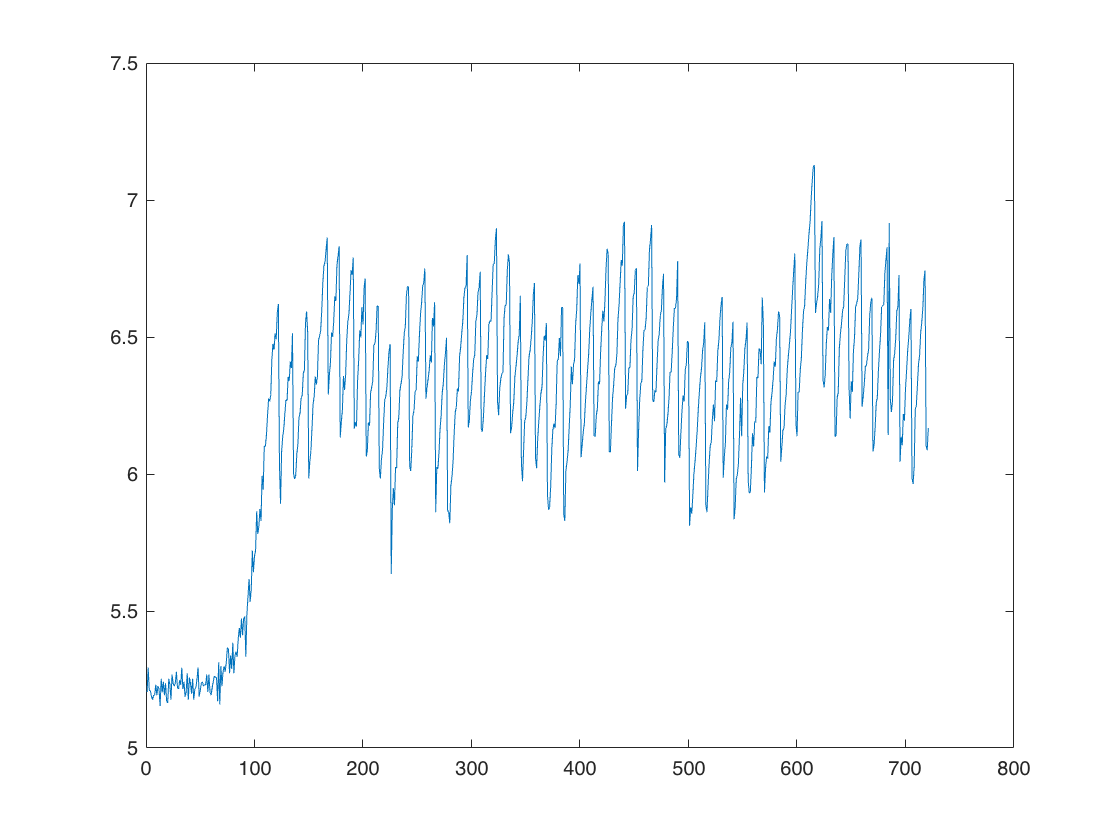

plot(log_area);

gr = diff(log_area);

Taking the derivative of the log area plot. Will set all values below the threshold of -0.4 to 0

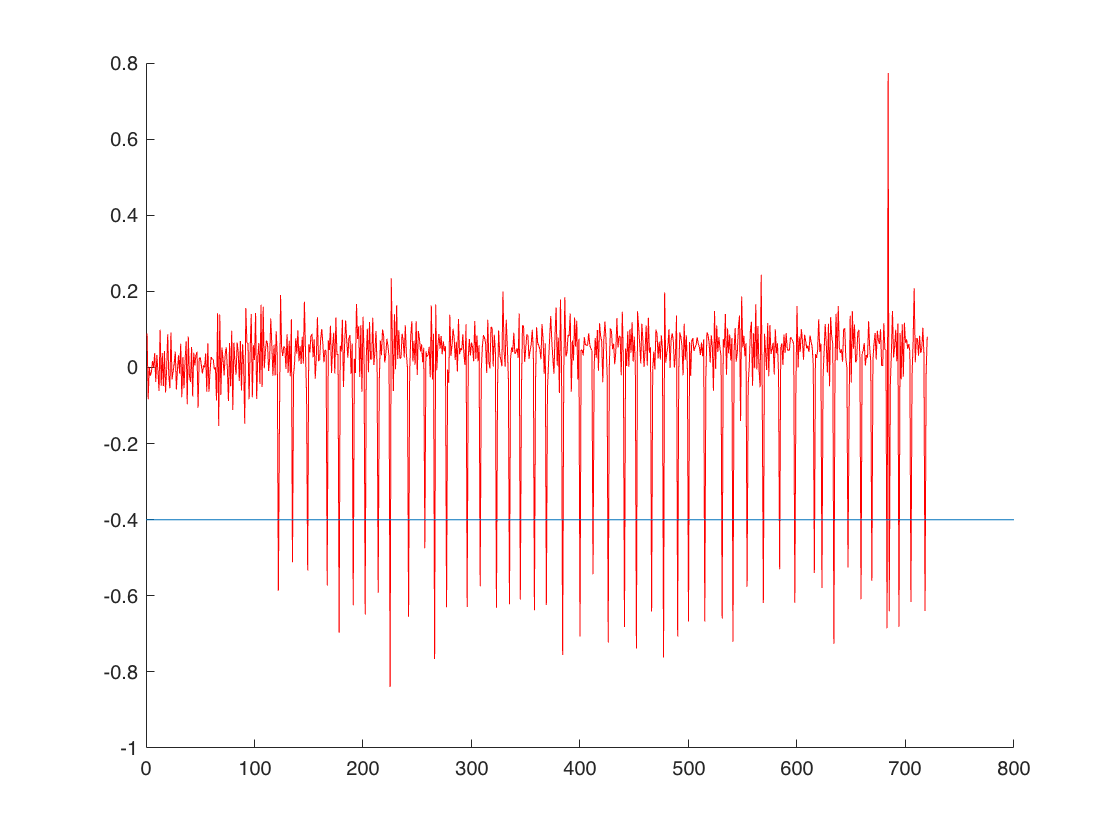

clf
hold on
plot(gr,'Color','r')
line([0,800],[1,1]*div_threshold)
hold off

Setting all values below the threshold of -0.4 to 0

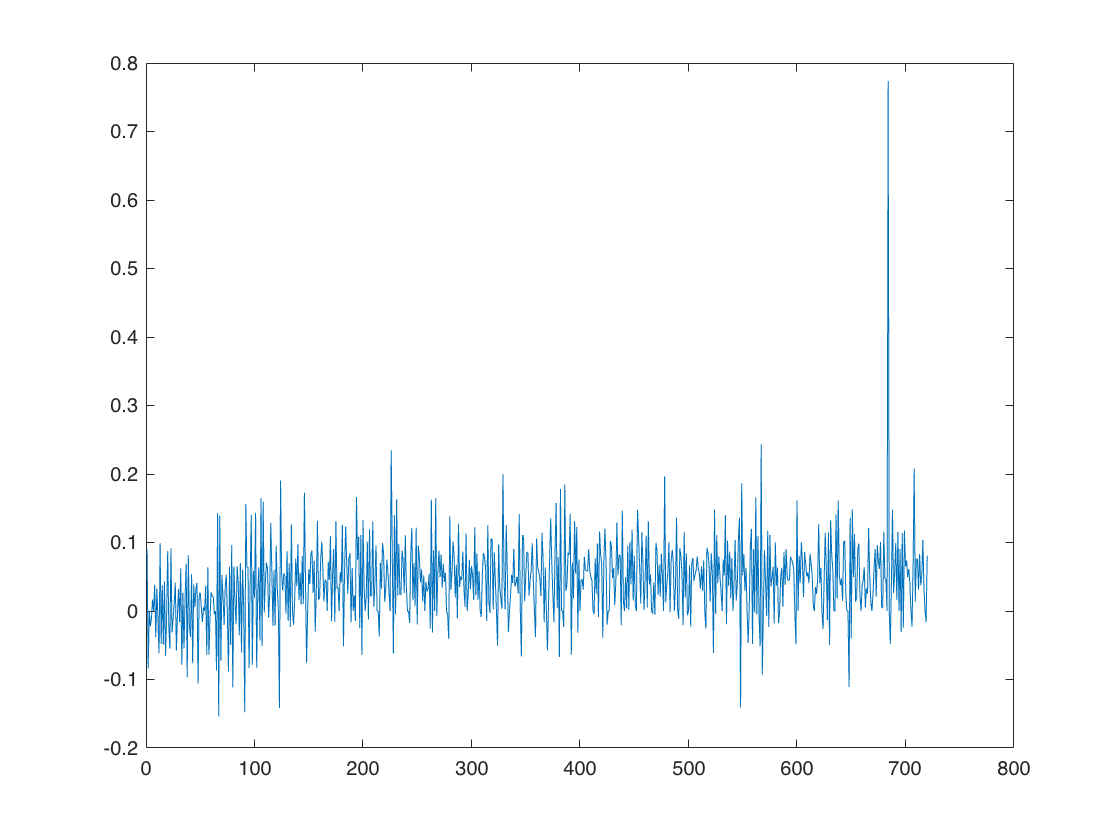

gr(gr<div_threshold)=0;
plot(gr)

Finding the cumulative sum of the above graph to find the lagtime graph

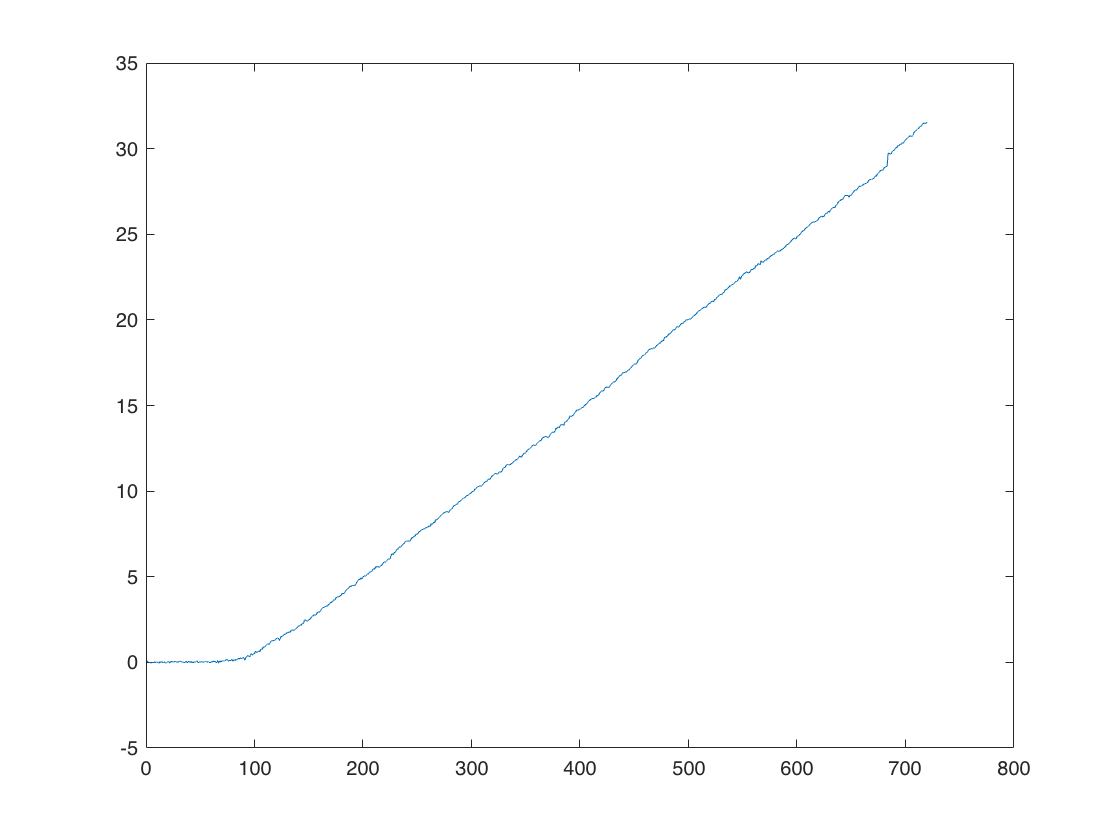

lagt = cumsum(gr);
plot(lagt)

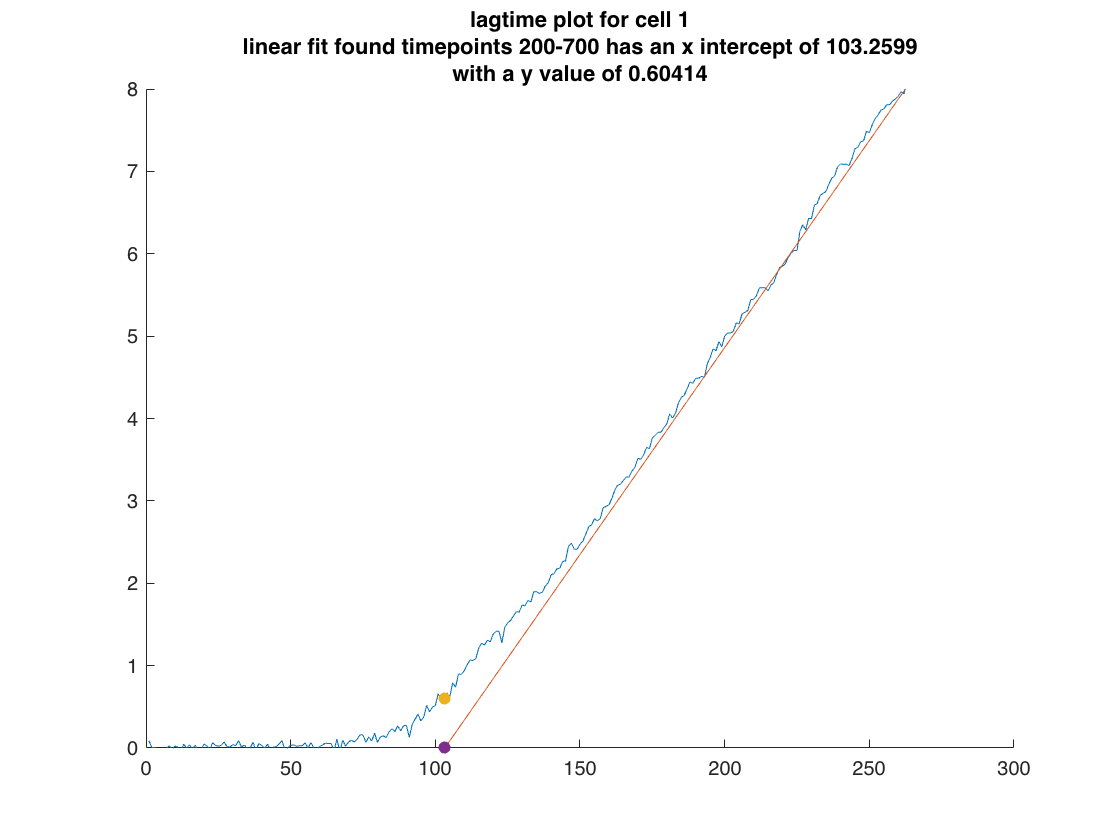


range_fit = 200:700;
p = polyfit(range_fit,lagt(1,range_fit),1);
fit = polyval(p,1:720);
clf
hold on
plot(lagt);
plot(1:720,fit);
x0 = interp1(fit,1:720,0);
title(["lagtime plot for cell "+1,"linear fit found timepoints 200-700 has an x intercept of "+ x0, "with a y value of "+lagt(round(x0))])
scatter(x0,lagt(round(x0)),'filled')
scatter(x0,0,'filled')
%xlim([0 200])
ylim([0 8])

The lagtime is the x intercept, hence this cell has a lagtime of 103.26 timepoints

Which is 206.5 minutes: 3h 26minutes at which point it reaches its exponential growth phase

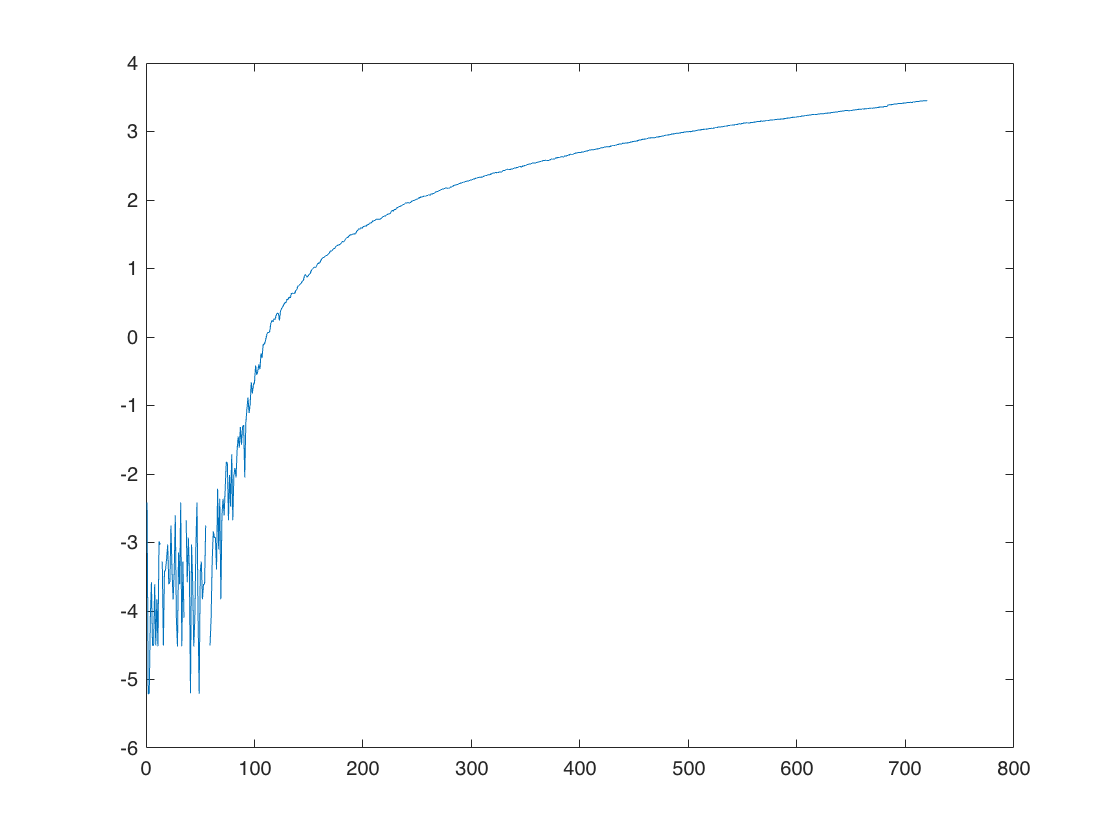

plot(real(log(lagt)))